Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


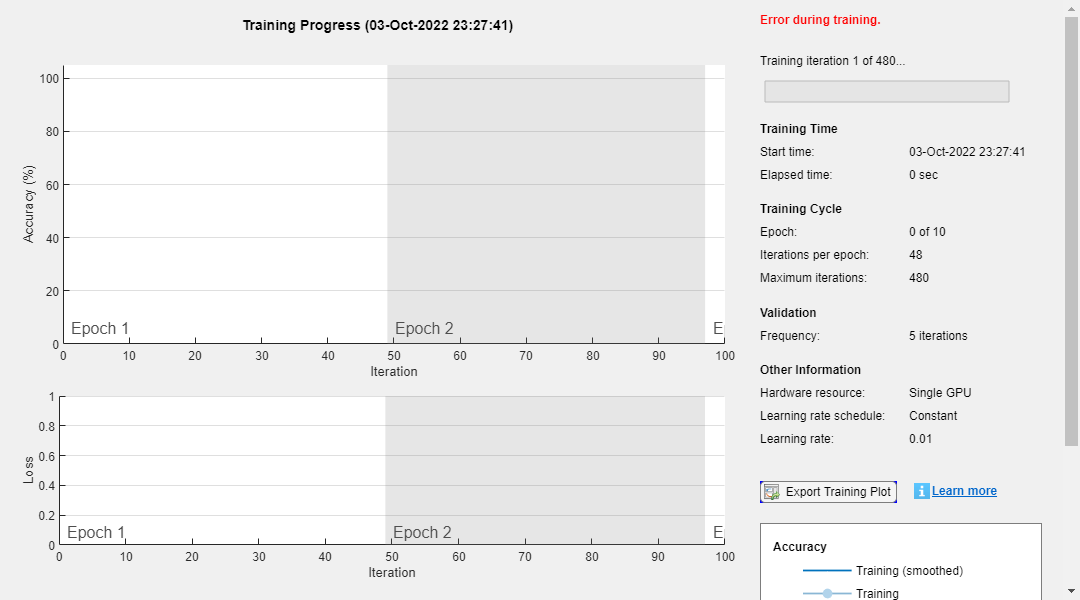

Error using trainNetwork
Out of memory.

Caused by:
    Out of memory.

Related documentation

imdsTrain = dsAll;
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 3],imdsTrain);
augimdsValidation = augmentedImageDatastore([224 224 3],imdsValidation);

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "L2Regularization",0.01,...
    "MaxEpochs",10,...
    "MiniBatchSize",256,...
    "Momentum",0.95,...
    "OutputNetwork","best-validation-loss",...
    "Shuffle","every-epoch",...
    "ValidationFrequency",5,...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

lgraph = layerGraph();

tempLayers = [
    imageInputLayer([224 224 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],32,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","batchnorm_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    reluLayer("Name","relu_5")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_6")
    convolution2dLayer([3 3],32,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","batchnorm_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","batchnorm_8")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    reluLayer("Name","relu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","batchnorm_9")
    reluLayer("Name","relu_8")
    convolution2dLayer([3 3],32,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","batchnorm_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_4")
    reluLayer("Name","relu_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_13","Padding","same")
    batchNormalizationLayer("Name","batchnorm_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","batchnorm_11")
    reluLayer("Name","relu_10")
    convolution2dLayer([3 3],32,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","batchnorm_12")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_5")
    reluLayer("Name","relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_14","Padding","same")
    batchNormalizationLayer("Name","batchnorm_14")
    reluLayer("Name","relu_12")
    convolution2dLayer([3 3],32,"Name","conv_15","Padding","same")
    batchNormalizationLayer("Name","batchnorm_15")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_6")
    reluLayer("Name","relu_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_16","Padding","same")
    batchNormalizationLayer("Name","batchnorm_16")
    reluLayer("Name","relu_14")
    convolution2dLayer([3 3],32,"Name","conv_17","Padding","same")
    batchNormalizationLayer("Name","batchnorm_17")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_18","Padding","same")
    batchNormalizationLayer("Name","batchnorm_18")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_7")
    reluLayer("Name","relu_15")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],32,"Name","conv_19","Padding","same")
    batchNormalizationLayer("Name","batchnorm_19")
    reluLayer("Name","relu_16")
    convolution2dLayer([3 3],32,"Name","conv_20","Padding","same")
    batchNormalizationLayer("Name","batchnorm_20")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_8")
    reluLayer("Name","relu_17")
    globalAveragePooling2dLayer("Name","gapool")
    fullyConnectedLayer(32,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

lgraph = connectLayers(lgraph,"maxpool","conv_2");
lgraph = connectLayers(lgraph,"maxpool","addition_1/in2");
lgraph = connectLayers(lgraph,"batchnorm_3","addition_1/in1");
lgraph = connectLayers(lgraph,"relu_3","conv_4");
lgraph = connectLayers(lgraph,"relu_3","addition_2/in2");
lgraph = connectLayers(lgraph,"batchnorm_5","addition_2/in1");
lgraph = connectLayers(lgraph,"relu_5","conv_6");
lgraph = connectLayers(lgraph,"relu_5","conv_8");
lgraph = connectLayers(lgraph,"batchnorm_7","addition_3/in1");
lgraph = connectLayers(lgraph,"batchnorm_8","addition_3/in2");
lgraph = connectLayers(lgraph,"relu_7","conv_9");
lgraph = connectLayers(lgraph,"relu_7","addition_4/in1");
lgraph = connectLayers(lgraph,"batchnorm_10","addition_4/in2");
lgraph = connectLayers(lgraph,"relu_9","conv_13");
lgraph = connectLayers(lgraph,"relu_9","conv_11");
lgraph = connectLayers(lgraph,"batchnorm_13","addition_5/in2");
lgraph = connectLayers(lgraph,"batchnorm_12","addition_5/in1");
lgraph = connectLayers(lgraph,"relu_11","conv_14");
lgraph = connectLayers(lgraph,"relu_11","addition_6/in1");
lgraph = connectLayers(lgraph,"batchnorm_15","addition_6/in2");
lgraph = connectLayers(lgraph,"relu_13","conv_16");
lgraph = connectLayers(lgraph,"relu_13","conv_18");
lgraph = connectLayers(lgraph,"batchnorm_17","addition_7/in1");
lgraph = connectLayers(lgraph,"batchnorm_18","addition_7/in2");
lgraph = connectLayers(lgraph,"relu_15","conv_19");
lgraph = connectLayers(lgraph,"relu_15","addition_8/in1");
lgraph = connectLayers(lgraph,"batchnorm_20","addition_8/in2");

[net, traininfo] = trainNetwork(augimdsTrain,lgraph,opts);